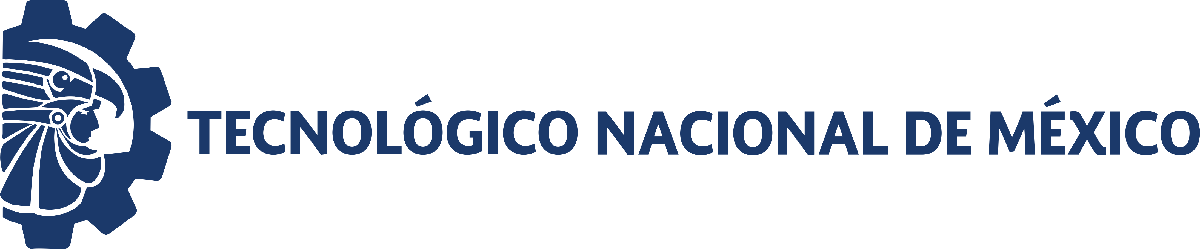                                 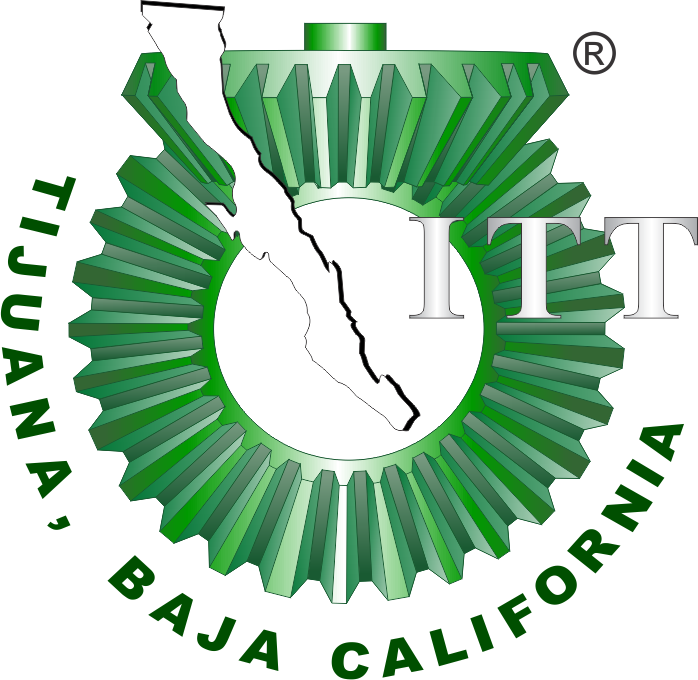

# Proyecto 00: Sistema respiratorio, asma

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

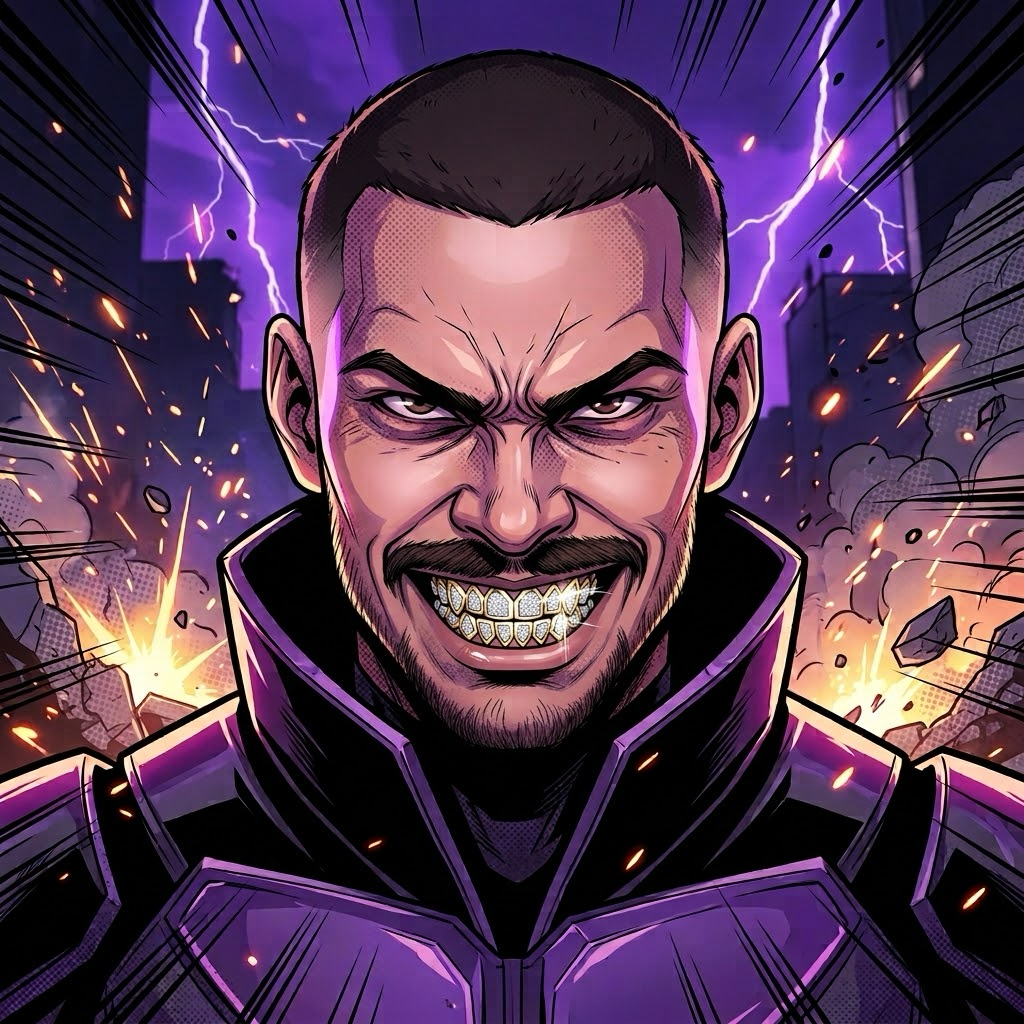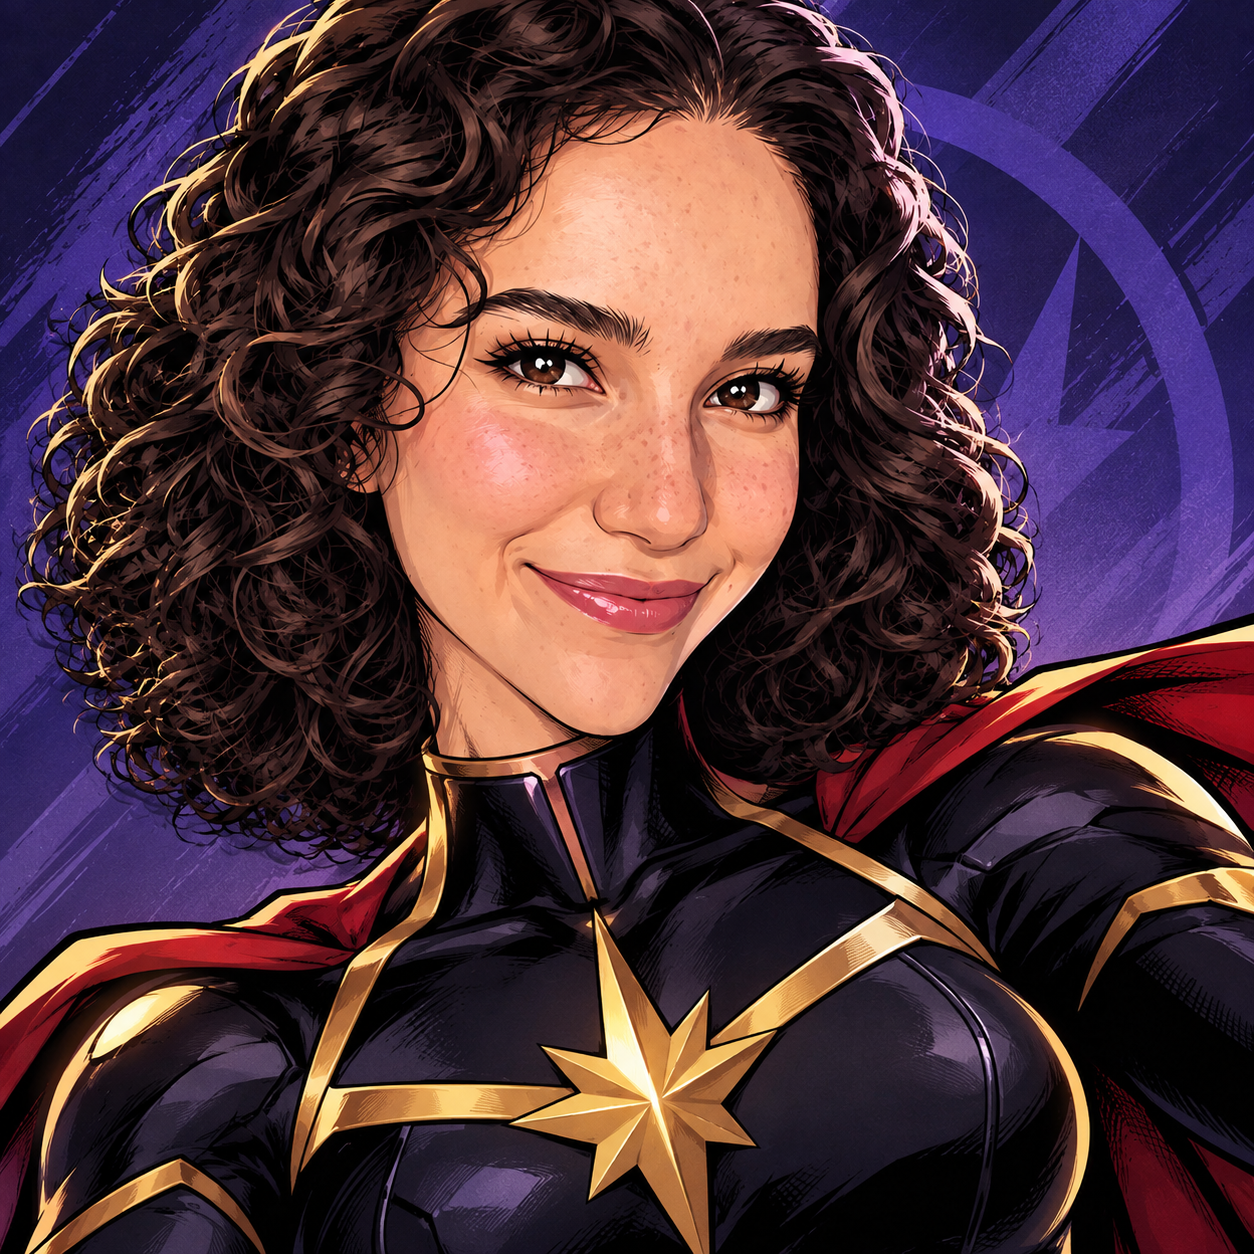

Nombre del alumno: Emiliano Villalobos García

Número de control: 23212243

Correo institucional: l23212243**@tectijuana.edu.mx**

Nombre del alumno: Sara Gutiérrez Hernández

Número de control: 23212734

Correo institucional: l23212734**@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all
open_system('Sistema1')
parameters.StopTime = '20';
parameters.Solver = 'ode15s';
parameters.MaxStep = '0.01';
parameters.ReturnWorkspaceOutputs = 'on';
parameters.SaveTime = 'on';
parameters.TimeSaveName = 't';
X = sim('Sistema1',parameters);

## Respuesta del modelo de Simulink

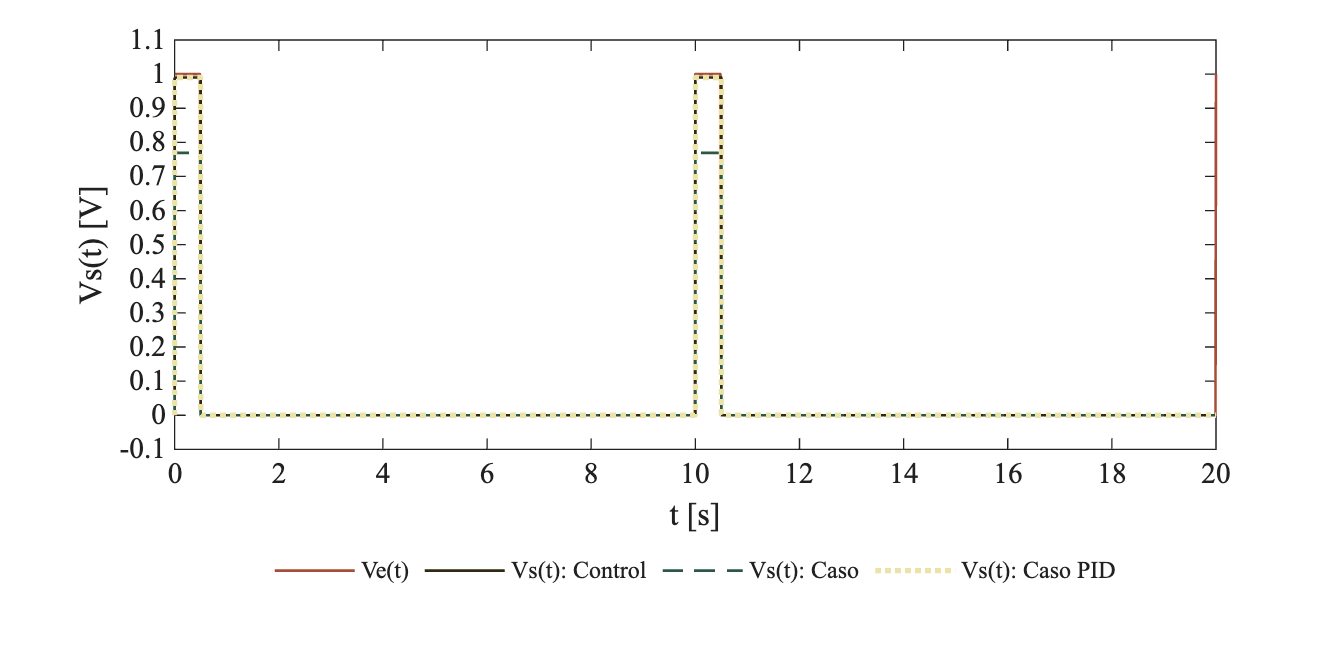

plotsignals(X.t,X.Ve,X.Fsx,X.Fsy,X.PID,'_matlab')

## Función: respuesta de la simulación

function plotsignals(t,Ve,control,caso,PID,nombre)
    set(figure(),'color','w')
    set(gcf,'units','inches','position',[1,1,7,3.5])
    set(gca,'fontname','times new roman','fontsize',11)
    hold on; grid off; box on

    clr1=[46,41,16]/255;
    clr2=[44,87,69]/255;
    clr3=[235,227,167]/255;
    clr4=[166,77,55]/255;

    plot(t,Ve,'-','LineWidth',1,'Color',clr4)
    plot(t,control,'-','LineWidth',1,'Color',clr1)
    plot(t,caso,'--','LineWidth',1,'Color',clr2)
    plot(t,PID,':','LineWidth',2,'Color',clr3)

    L=legend('Ve(t)','Vs(t): Control','Vs(t): Caso','Vs(t): Caso PID');
    set(L,'FontSize',9,'Location','southoutside','Orientation','horizontal','Box','off')

    xlabel('t [s]'); ylabel('Vs(t) [V]')
    
    xlim([0,20]); xticks(0:2:20)
    ylim([-0.1,1.1]); yticks(-0.1:0.1:1.1)
    exportgraphics(gcf,['caso' nombre '.pdf'],'ContentType','vector')
end